% Variieren der Hyperparameter sigmaF, sigmaN, l und berechnen der logLikelihood
close
clear
clc
load dataOut/testData4.mat

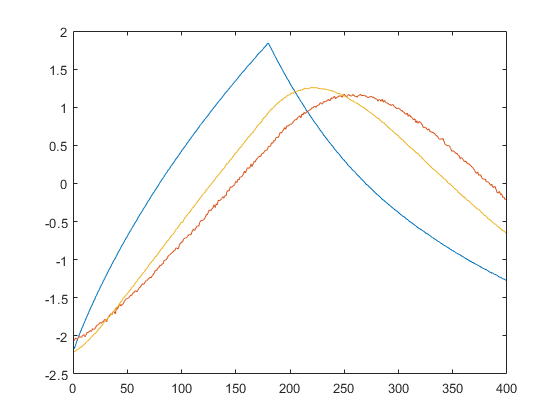


%xD = [testData.x1, testData.x2, testData.x3, testData.u];
xD = [testData.dx32, testData.dx32];
dxD = [testData.dx1, testData.dx2, testData.dx3];
yD = [testData.y1, testData.y2, testData.y3];

D = size(yD,1);
n = size(xD,2);
m = size(yD,2);

for i = 1 : n
    xStd(1,i) = std(xD(:,i));
    xMean(1,i) = mean(xD(:,i));

end
for i = 1 : m
    dxStd(1,i) = std(dxD(:,i));
    dxMean(1,i) = mean(dxD(:,i));

    yStd(1,i) = std(yD(:,i));
    yMean(1,i) = mean(yD(:,i));
end

xDnorm = (xD - xMean)./ xStd;
dxDnorm = (dxD - dxMean)./ dxStd;
yDnorm = (yD - yMean)./ yStd;

plot(yDnorm)

gpml methods

  meanfunc = [];                    % empty: don't use a mean function
  covfunc = @covSEiso;              % Squared Exponental covariance function
  likfunc = @likGauss;              % Gaussian likelihood
hyp = struct('mean', [], 'cov', [0 0], 'lik', -1);
hyp2 = minimize(hyp, @gp, -100, @infGaussLik, meanfunc, covfunc, likfunc, xDnorm, dxDnorm(:,3));

Function evaluation      0;  Value 1.217395e+03
Function evaluation      9;  Value 5.500728e+02
Function evaluation     12;  Value 5.431193e+02
Function evaluation     13;  Value 5.430119e+02
Function evaluation     15;  Value 5.427065e+02
Function evaluation     18;  Value 5.420977e+02
Function evaluation     20;  Value 5.418495e+02
Function evaluation     22;  Value 5.415621e+02
Function evaluation     24;  Value 5.415515e+02
Function evaluation     25;  Value 5.415398e+02
Function evaluation     27;  Value 5.415306e+02
Function evaluation     29;  Value 5.415201e+02
Function evaluation     31;  Value 5.415136e+02
Function evaluation     33;  Value 5.415047e+02
Function evaluation     35;  Value 5.415000e+02
Function evaluation     37;  Value 5.414946e+02
Function evaluation     38;  Value 5.414894e+02
Function evaluation     40;  Value 5.414863e+02
Function evaluation     42;  Value 5.414796e+02
Function evaluation     44;  Value 5.414788e+02
Function evaluation     47;  Value 5.414


hyperparameter.l = exp(hyp2.cov(1)); %length scale
hyperparameter.sigmaF = exp(hyp2.cov(2)); %signal std Dev sigmaF
hyperparameter.sigmaN = exp(hyp2.lik(1)); %noise std dev sigmaN
hyperparameter

hyperparameter = struct with fields:
         l: 0.8365
    sigmaF: 0.4727
    sigmaN: 0.9218


**Variation aller Hyperparameter gleichzeitig**

%sigmaF = (logspace(-3,0,50)).';
%sigmaN = (logspace(-3,0,50)).';
%l = (logspace(0,1,20)).';


sigmaF = (0.7:0.01:1).';
sigmaF = (0.9:-0.01:0.5);
sigmaF = 0.86;
sigmaN = (0.5:0.01:0.8).';
sigmaN = 0.56;
l = (0.1:0.01:6).';
logLike = zeros(length(sigmaF),length(sigmaN),length(l));
for i = 1: length(sigmaF)
    for j = 1: length(sigmaN)
        for k = 1: length(l)
        K=CovMatrix(xDnorm,sigmaF(i),l(k));
        logLike(i,j,k)=logLikelihood_V1(dxDnorm(:,1),K,sigmaN(j)); 
        end
    end
end

Finden des Maximums 

maxLik=max(logLike(~isinf(logLike)))
%[sigmaFmax sigmaNmax lMax ] = find(lL_FNl == maxLik)
[r,c,v] = ind2sub(size(logLike),find(logLike == maxLik))
sigmaFmax = sigmaF(r)
sigmaNmax = sigmaN(c)
lMax = l(v)

% save('hyperparameter','logLike','sigmaF','sigmaN','l','sigmaFmax','sigmaNmax','lMax')

Plotten der Höhenlinien

% l fixiert
[x,y] = meshgrid(sigmaF,sigmaN);
x =x.';
y = y.';
logLike_lmax = logLike(:,:,v);

figure(1)
%contour(x,y,logLike_lmax,'ShowText','on')
%ylim([0.1 0.5]);
%xlim([0 0.5]);
xlabel('sigmaF')
ylabel('sigmaN')

**Hyperparameter am Optimum festhalten und einen variieren**

% sigma F varrieren
sigmaF = (0.1:0.01:0.4).';
sigmaN = 0.35;
l = 0.34;
logLike_sF = zeros(size(sigmaF));
for i = 1: length(sigmaF)
        K=CovMatrix([u,x],sigmaF(i),l);
        logLike_sF(i)=logLikelihood_V1(dx,K,sigmaN);
end
figure(2)
plot (sigmaF, logLike_sF)
xlabel('sigmaF')
ylabel('logLike')

% sigma N varrieren
sigmaF = 0.3;
sigmaN = (0.3:0.01:0.5).';
l = 0.4;
logLike_sN = zeros(size(sigmaN));
for i = 1: length(sigmaN)
        K=CovMatrix([u,x],sigmaF,l);
        logLike_sN(i)=logLikelihood_V1(dx,K,sigmaN(i));
end
figure(3)
plot (sigmaN, logLike_sN)
xlabel('sigmaN')
ylabel('logLike')

% l varrieren
sigmaF = 0.1;
sigmaN = 0.35;
l =(0.1:0.1:5).';
logLike_l = zeros(size(l));
for i = 1: length(l)
        K=CovMatrix([u,x],sigmaF,l(i));
        logLike_l(i)=logLikelihood_V1(dx,K,sigmaN);
end
figure(4)
plot (l, logLike_l)
xlabel('l')
ylabel('logLike')